## EXERCISE 2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms x y

% Exercise 1
fx = x*(3-x-2*y)

$$fx = -x\,\left(x+2\,y-3\right)$$

fy = y*(2-x-y)

$$fy = -y\,\left(x+y-2\right)$$

% setting the matlab function for our system
f_lmb = @(t,z) [z(1)*(3 - z(1) - 2*z(2)); z(2)*(2 - z(1) - z(2))];

a)

% CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: [4×1 sym]
    y: [4×1 sym]


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =      0     3     0     1
     0     0     2     1



% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);
eigenvectors = zeros(2, 2, size(fixPts, 2));

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    [eigenvectors(:,:,k), D] = eig(JacFixPts(:,:,k));
    eigenvalues(k, :) = diag(D);
end

% IDENTIFY IF THE FIXED POINTS ARE HYPERBOLIC
% CLASSIFICATION OF THE FIXED POINTS
for k = 1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) == 0)
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.000000, 0.000000) is hyperbolic.
Fixed point at (3.000000, 0.000000) is hyperbolic.
Fixed point at (0.000000, 2.000000) is hyperbolic.
Fixed point at (1.000000, 1.000000) is hyperbolic.



% Represent the fixed points and the eigenvalues
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');

b)

% COMPUTE THE NULLCLINES
xcline_x = solve(fx == 0, x);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-eps 3.5 -eps 2.5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 3.5 -eps 2.5], 'g--', 'LineWidth', 1.5);

d)

% 6. REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(0, 4, N);
ylin = linspace(0, 2.5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);
% Computing the grid
fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

% Computing the flow of the system with quiver
flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-eps 3.5 -eps 2.5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

c) e) y g)

% REPRESENT A TRAJECTORY 
t0 = 0.5; tf = 30;
tspam = [t0,tf];

% Initialise at (1, 0.6)
y0 =[1 0.6];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (0.5, 1)
y0 =[0.5 1];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (1, 2)
y0 =[1 2];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj3 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% Initialise at (2, 1)
y0 =[2 1];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj4 = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');


f)

% 8. REPRESENT THE BASINS OF ATTRACTION IN THE PHASE DIAGRAM
% 9. PAINT A TRAJECTORY FOR EACH BASIN
eps = 1e-3

eps = 1.0000e-03

t0 = 0.5; tf = 30;
tspam = [t0,tf];

y0 = (eigenvectors(:, 1, 4)*eps)+fixPts(:,4)

y0 =     1.0008
    0.9994


[ts,ys] = ode45(f_lmb,tspam, y0);
basin1 = plot(ys(:,1),ys(:,2),'r-');

y0 = -(eigenvectors(:, 1, 4)*eps)+fixPts(:,4)

y0 =     0.9992
    1.0006


[ts,ys] = ode45(f_lmb,tspam, y0);
basin2 = plot(ys(:,1),ys(:,2),'r-');

% Now for the stable manifold time is reversed
tspam = [tf,t0];

y0 = (eigenvectors(:, 2, 4)*eps)+fixPts(:,4)

y0 =     1.0008
    1.0006


[ts,ys] = ode45(f_lmb,tspam, y0);

basin3 = plot(ys(:,1),ys(:,2),'black-');

y0 = -(eigenvectors(:, 2, 4)*eps)+fixPts(:,4)

y0 =     0.9992
    0.9994


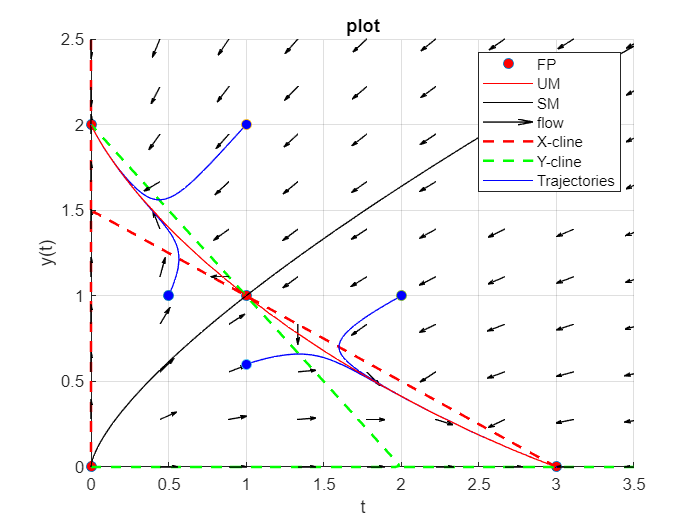

[ts,ys] = ode45(f_lmb,tspam, y0);
basin4 = plot(ys(:,1),ys(:,2),'black-');

xlabel('t');ylabel('y(t)');grid on; title('plot')
legend([fpts basin1 basin3 flow nullX nullY traj1], ...
    {'FP', 'UM', 'SM', 'flow', 'X-cline', 'Y-cline', 'Trajectories'}, ...
    'Location', 'NorthEast')


disp('Trajectories starting below the stable manifold lead to eventual extinction of the sheep, while those starting above lead to eventual extinction of the rabbits. Thus, the one initiated at (1, 0.6) lead to the extinction of sheeps.')

Trajectories starting below the stable manifold lead to eventual extinction of the sheep, while those starting above lead to eventual extinction of the rabbits. Thus, the one initiated at (1, 0.6) lead to the extinction of sheeps.


disp('Also, it is seen than below the Stable Manifold (black) is the basin for (3,0), and above it for (0,2)')

Also, it is seen than below the Stable Manifold (black) is the basin for (3,0), and above it for (0,2)


disp('FP - Fixed Point')

FP - Fixed Point


disp('UM - Unstable Manifold')

UM - Unstable Manifold


disp('SM - Stable Manifold')

SM - Stable Manifold
